# Compressive temporal summation tutorial

## This code accompanies the JNS paper "Compressive temporal summation in human visual cortex" published in 2017.

In this code, we are going to create a stimulus time course, and analyze both the time course and the fMRI (summed time course) predictions from 3 models:

(1) Linear model

(2) Static temporal nonlinear model (STN, the main model in the paper, or CTS model variant 1)

(3) Exponentiated temporal compressivion (ETC, a variant of the CTS model using an exponent)

(4) Two-temporal channels model (TTC model)

## MAKE A STIMULI

t     = 0.001 : 0.001 : 1;
t_lth = length(t);

stim  = zeros(2, t_lth);

stim(1, t<0.1) = 1;
stim(2, t<0.2) = 1;


## VISUALIZE STIMULI

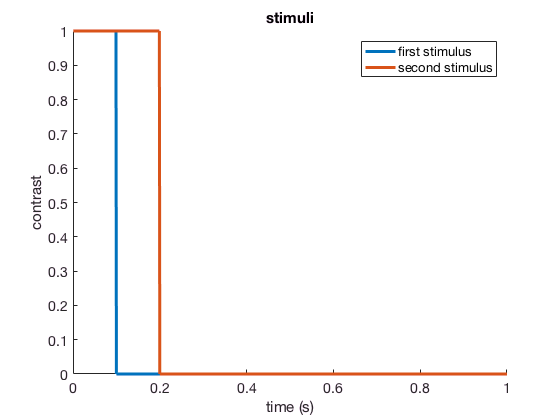

figure (1), clf
plot(t, stim, 'linewidth', 3), box off
xlabel('time (s)'), ylabel('contrast'), legend('first stimulus', 'second stimulus'), title('stimuli')
set(gca, 'fontsize', 14)

## COMPUTE MODEL PREDICTIONS

## Initialize

param = []; % model parameters
rsp   = []; % model responses


## Compute linear model predictions

param.lin(1) = 1; % scale 

% model prediction
[~, rsp.lin.tc]  = trf_LinModel(param.lin, stim, t); % time course prediction
rsp.lin.fmri = sum(rsp.lin.tc, 2);

## Compute STN model predictions (main implementation of the CTS model in the paper)

param.stn(1) = 0.08; % tau
param.stn(2) = 0.1; % sigma
param.stn(3) = 1;   % scale

% model prediction
rsp.stn.tc   = trf_STNmodel(param.stn, stim, t, 1); % time course response
rsp.stn.fmri = sum(rsp.stn.tc, 2);

## Compute ETC model predictions

param.etc(1) = 0.08; % tau
param.etc(2) = 0.5; % exponent
param.etc(3) = 1; % scale 

% model prediction
rsp.etc.tc = trf_ETCmodel(param.etc, stim, t, 1);
rsp.etc.fmri = sum(rsp.etc.tc, 2);


## Compute the two temporal channels model prediction

param.ttc(1) = 0.01; % weight of the sustained channel
param.ttc(2) = 0.005; % weight of the transient channel;

%normMax = @(x) x./max(x);

% model prediction
rsp.ttc.tc = trf_2chansModel(param.ttc, stim, t);
rsp.ttc.fmri = sum(rsp.ttc.tc, 2);


## Visualize model predictions

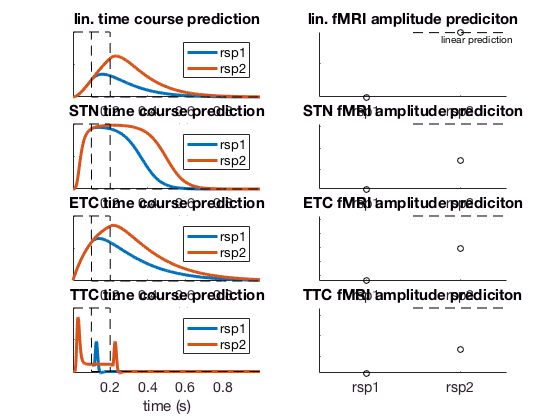

figure (2), clf
 
modelNm = {'lin.','', 'STN', '', 'ETC', '', 'TTC'};

% plot linear model prediction
subplot(4, 2, 1), plot(t, rsp.lin.tc, 'linewidth', 3), hold on, axis tight,
subplot(4, 2, 2), plot(rsp.lin.fmri, 'ko'), hold on, xlim([0.5, 2.5]), ylim([rsp.lin.fmri(1), rsp.lin.fmri(1) * 2 + 1])
plot([1.5, 2.5], [rsp.lin.fmri(1) * 2, rsp.lin.fmri(1) * 2], 'k--'), text(1.8, rsp.lin.fmri(1) * 2-10, 'linear prediction' )

% plot stn model prediction
subplot(4, 2, 3), plot(t, rsp.stn.tc, 'linewidth', 3), hold on, axis tight, 
subplot(4, 2, 4), plot(rsp.stn.fmri, 'ko'), hold on, xlim([0.5, 2.5]), ylim([rsp.stn.fmri(1), rsp.stn.fmri(1) * 2]), 
plot([1.5, 2.5], [rsp.stn.fmri(1) * 2, rsp.stn.fmri(1) * 2], 'k--')
% plot etc model prediction
subplot(4, 2, 5), plot(t, rsp.etc.tc, 'linewidth', 3), hold on, axis tight, 
subplot(4, 2, 6), plot(rsp.etc.fmri, 'ko'), hold on,  xlim([0.5, 2.5]), ylim([rsp.etc.fmri(1), rsp.etc.fmri(1) * 2])
plot([1.5, 2.5], [rsp.etc.fmri(1) * 2, rsp.etc.fmri(1) * 2], 'k--')

% plot 2-temporal channels model prediction
subplot(4, 2, 7), plot(t, rsp.ttc.tc, 'linewidth', 3), hold on, axis tight
subplot(4, 2, 8), plot(rsp.ttc.fmri, 'ko'), hold on, xlim([0.5, 2.5]), ylim([rsp.ttc.fmri(1), rsp.ttc.fmri(1) * 2])
plot([1.5, 2.5], [rsp.ttc.fmri(1) * 2, rsp.ttc.fmri(1) * 2], 'k--')


for k = 1 : 8
    subplot(4, 2, k), box off,  set(gca, 'yticklabel', ''), set(gca, 'fontsize', 14)
end

for k = 1 : 2 : 8, subplot(4, 2, k), legend('rsp1', 'rsp2'), plot(t, stim, 'k--'),
    title(sprintf('%s time course prediction', modelNm{k})), xlabel('time (s)'), end

for k = 2 : 2 : 8, subplot(4, 2, k), set(gca, 'xtick', [1, 2], 'xticklabel', {'rsp1', 'rsp2'}),
    title(sprintf('%s fMRI amplitude prediciton', modelNm{k-1})), end